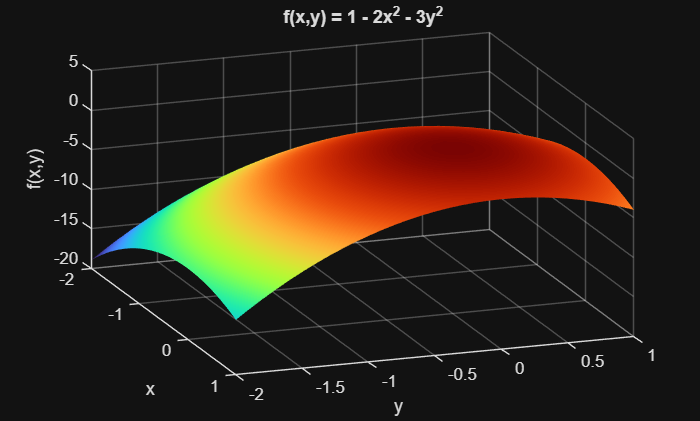

% 2026-10-05, Variantas: 24, Jokūbas Bridikis
 
clear; clc; close all;
 
[x, y] = meshgrid(-2:0.1:1, -2:0.1:1);
z = 1 - 2*x.^2 - 3*y.^2;
 
figure
surf(x, y, z)
shading interp
colormap(turbo)
view(70, 30)
xlabel('x')
ylabel('y')
zlabel('f(x,y)')
title('f(x,y) = 1 - 2x^2 - 3y^2')
grid on

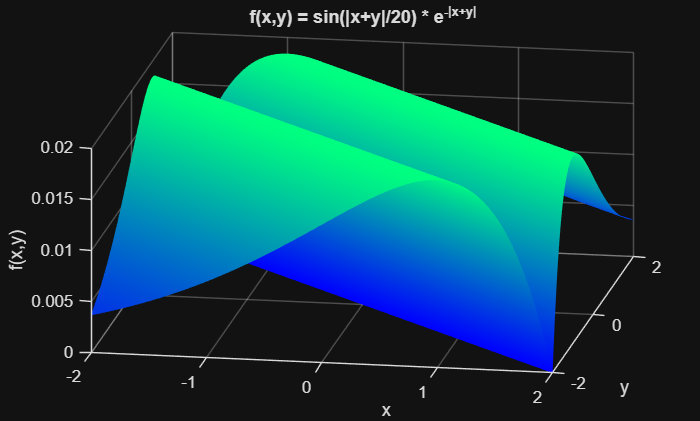

 
[x2, y2] = meshgrid(-2:0.05:2, -2:0.05:2);
z2 = sin(abs(x2 + y2)/20) .* exp(-abs(x2 + y2));
 
figure
surf(x2, y2, z2)
shading interp
colormap(winter)
view(10, 30)
xlabel('x')
ylabel('y')
zlabel('f(x,y)')
title('f(x,y) = sin(|x+y|/20) * e^{-|x+y|}')
grid on

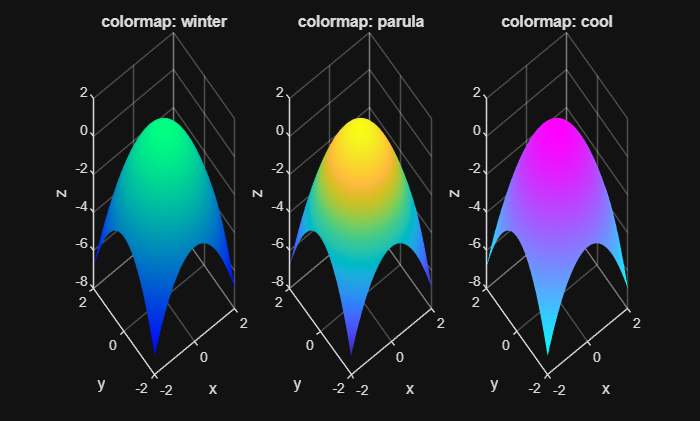

%papildoma
 % 2026-10-05, Variantas: 9, Jokūbas Bridikis
 
clear; clc; close all;
 
[x, y] = meshgrid(-2:0.1:2, -2:0.1:2);
z = 1 - (x.^2 + y.^2);
 
figure
 
subplot(1,3,1)
surf(x, y, z)
shading interp
colormap(gca, winter)
xlabel('x')
ylabel('y')
zlabel('z')
title('colormap: winter')
grid on
 
subplot(1,3,2)
surf(x, y, z)
shading interp
colormap(gca, parula)
xlabel('x')
ylabel('y')
zlabel('z')
title('colormap: parula')
grid on
 
subplot(1,3,3)
surf(x, y, z)
shading interp
colormap(gca, cool)
xlabel('x')
ylabel('y')
zlabel('z')
title('colormap: cool')
grid on